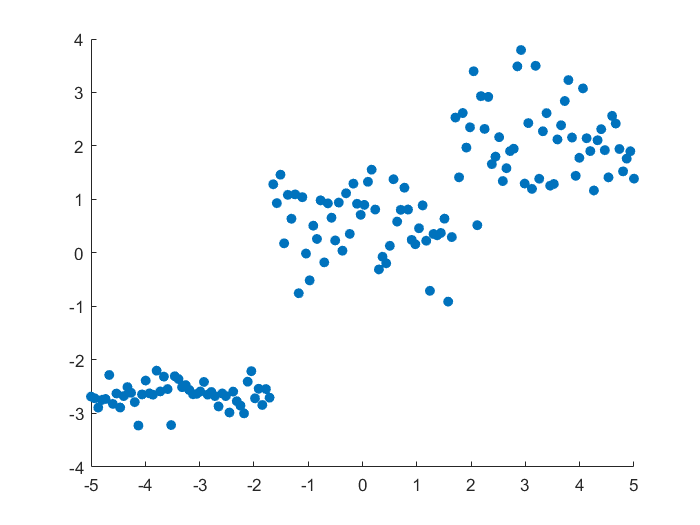

clc
clear;
filename = 'E:\研究生学习\模式识别\数据\train-images.idx3-ubyte';
[A,B]=iris_dataset;
B = vec2ind(B)';
%% center
X = iris_dataset';
X_m = mean(X);
X_T = X - ones(length(X),1)*X_m;
m = mean(X_T');
% calculate Colvariance Matrix
%F = X_T'*X_T/length(X);
C = cov(X);
% find PC1~
%[coeff,score,latent,tsquared,explained,mu] = pca(X);
[V, D] = eig(C);
[emax,emax_ind] = max(diag(D));
u = V(:,emax_ind);
% transform data
z = X*u;
Y = z*u';
[U, Z] = pca(X);
% sort
lambda = diag(wrev(diag(D)));
vector = fliplr(V);    %左右镜像矩阵
% sort2
lambda3 = diag(cumsum(diag(D))/sum(diag(D)));
max = X_T*vector;
% contribution
lambda2 = lambda/sum(diag(lambda));
figure;
rangee = linspace(-5,5,length(max));
scatter(rangee,max(:,1),'filled');

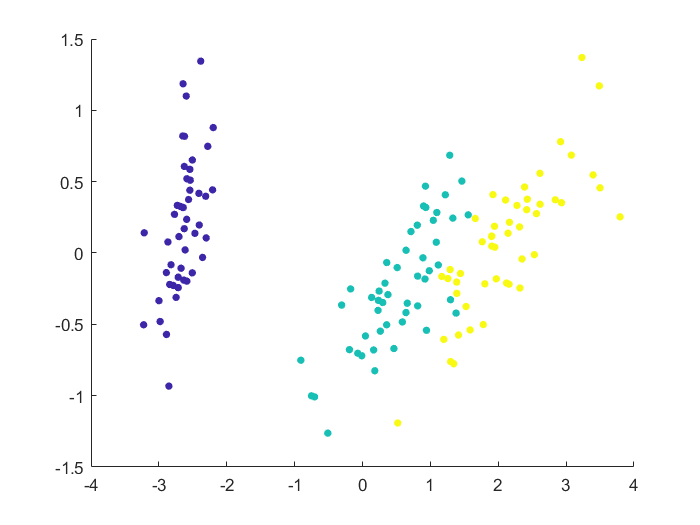

%gscatter(max(:,1),max(:,2),+,{'r','g','b'});
scatter(max(:,1),max(:,2),20,B,'filled');

%plotmatrix(max);
%plot(data,'+');

FID = fopen('E:\研究生学习\模式识别\数据\train-images.idx3-ubyte','r');
